# Visualización de imágenes

%%
clear all
cd("/home/erit/Desktop/SIMLab_2025")

Las imágenes son matrices cuyas celdas contienen informaicón acerca del nivel de brillo de la imagen. En el caso de las imágenes a color estas se construyen a partir de la concatenación de 3 o 4 matrices de las mismas dimensiones, donde cada una de ellas contiene la informaciónde brillo de las capas "RGB" (rojo, verde y azul) o "CMYK" (cyan, magenta, amarillo y negro).

En el caso de sistemas de visualización y cómputo, el color que se asigna a una imagen corresponde con el índice del **mapa de color. **Este es un elemnto dentro del sistema que indica cuales son los colores a ser usados en un proceso de graficación.

## Generación de una imagen de ruido


$$X = \left[ 
\begin{array}{cccc}
p_{0,0} &  p_{0,1} & \dots & p_{0,M-1} \\
p_{1,0} & p_{1,1} &  \dots &  p_{1,M-1} \\
\vdots  & \vdots & \ddots & \vdots \\
p_{N-1,0} & p_{N-1,1} &  \dots &  p_{N-1,M-1} \\
\end{array}\right]$$


La imagen **X ** queda definda por la secuencia de pixeles y tiene dimensiones de N renglones por M columnas. Ahora se definirá una matriz X que de 8 x 10 con valores enteros en su interior 

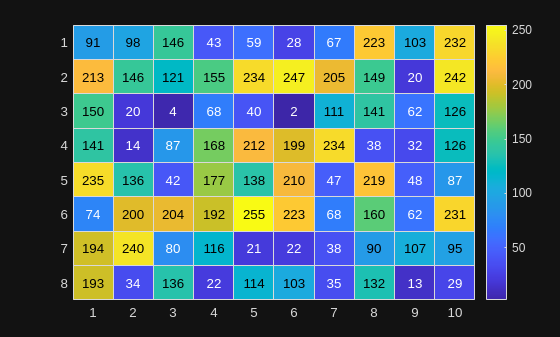

%%
X = randi([1,256],[8,10],'uint8');

h = heatmap(X);
h.Colormap = parula;

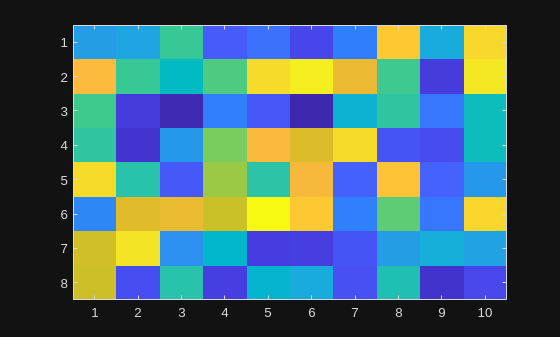

%%
image(X)
colormap("parula")

La imagen muestra una serie de tonos de azul a amarillo dispuesto de forma desordenada, ya que se generó una matriz con valores aleatorios entre 1 y 256. Los colores que fueron asignados a esta imagen correponden al mapa de color por omisión con el cual arranca el sistema Matlab y cuyos valores se pueden consultar con el comando: *colormap().*

Este comando nos permite poder cambiar el mapa de color de cualquier imagen ya sea modificando el número de niveles, definiendo la combinación de colores o usando algunos de los mapas de color preestablecidos por Matlab.

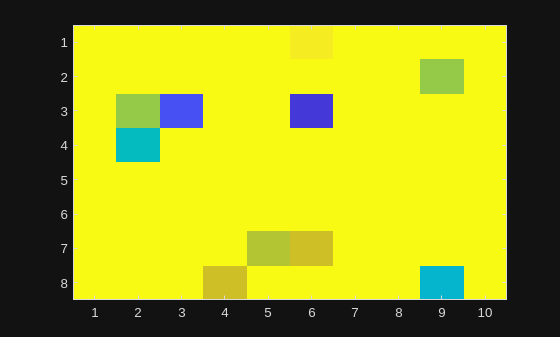

%%
% cambiando el mapa de color a solo 30 elementos
colormap(parula(30))

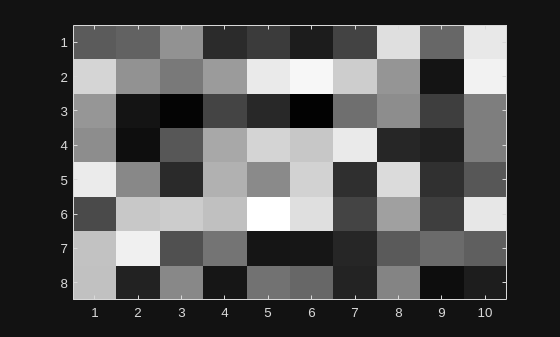


% cambiando el mapa de color a gris
colormap(gray(256))


% regresando al mapa original
colormap(parula(256))

## Generación de un gradiente de color

El mapa de color actual tiene 256 niveles, se generará una imagen de 10x256 pixeles que vaya cambiando en cada columna un valor para poder visulizar un gradiente horizontal de color de acuerdo al mapa actual

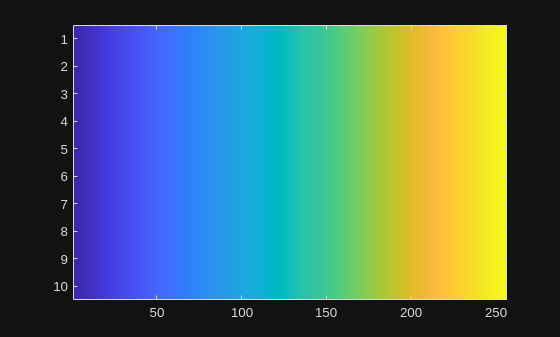

%%
X = 1:256;

% generación de un vector columna de 1 para usar que el resultado
% del producto interior sea la matriz que deseamos
X = ones(10,1) * X;
image(X);

Para volverlo vertical, basta con visualizarlo como la traspuesta de la matriz (X')

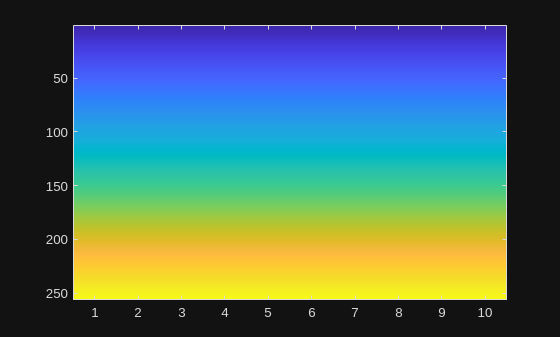

%%
image(X')

La imagen se ve del mismo tamaño y es que el sistema de visualización hace que la imagen ocupe todo el espacio de la misma. Para que los pixeles sean cuadrados se utiliza el comando: *axis equal*

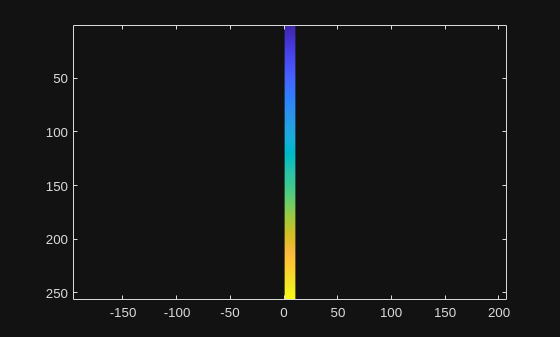

%%
% pixeles cuadrados
axis equal

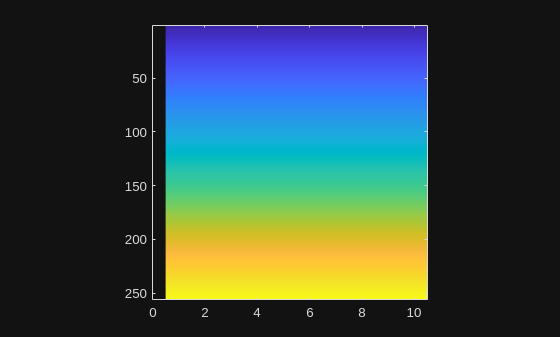


%%
% gráfico cuadrado
axis square

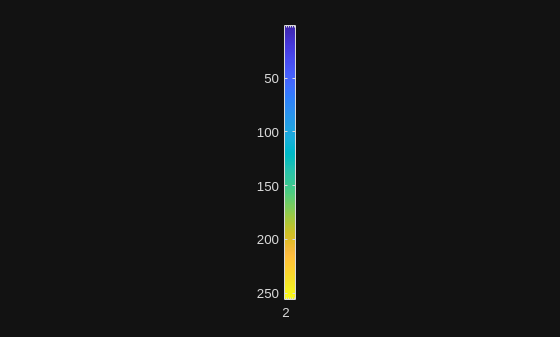


%%
% gráfico de imagen
axis image

Cambiaremos el mapa de color a color gris y jugaremos con el número de saltos para encontrar cual es el númepr de niveles capace de distinguir

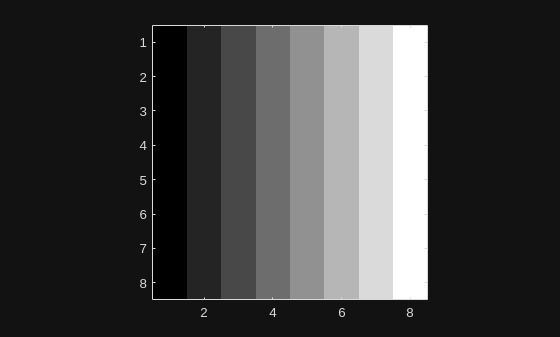

%%
gradiente_gris(8);

## Excedentes de nivel de gris

El color que se coloca corresponde al índice de cada nivel de gris. Si el número excede el nivel de gris se asigna al más próximo. Se creará un *colormap * de 8 niveles y se asignarán valores por debajo del mínimo (1) y máximo (8).

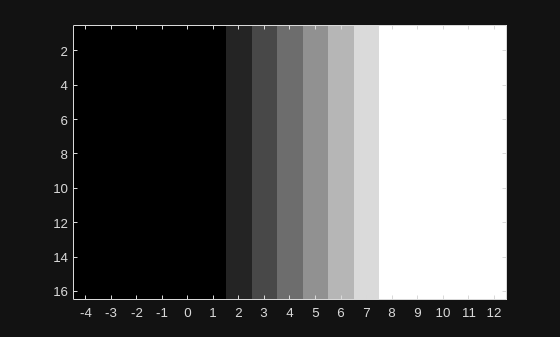

%%
% Se construye el vector y matirz con valores de -4 a 12

x_values = (-4:12);
X = ones(16,1) * x_values;

image(X);
xticks(1:length(x_values));
xticklabels(string(x_values));
colormap(gray(8))

## Ajustando los valores para visualización

Una imagen puede ser generada a partir de funciones matemáticas que no necesariamente den número enteros. Es por ello que el rango de los valores se debe ajustar para la correcta visualización. **Recordar que los valores de la imagen corresponden al índice del *****colormap****.*

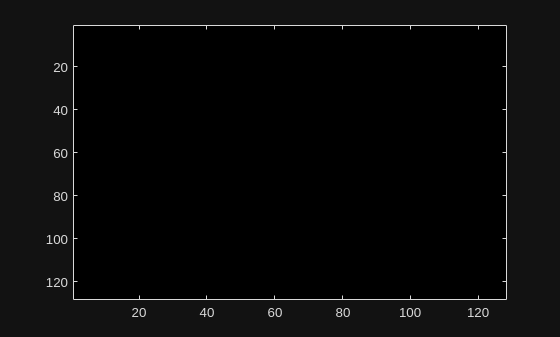

%% 

% Revisar los valores mínimos y máximos de esta descripción de función
X = ones(128,1) * (0.5 + sin(pi * (1:128)/32));
image(X);
colormap(gray(128));

% Display the minimum and maximum values of the modified matrix
disp(['Minimum value: ', num2str(min(X(:)))]);

Minimum value: -0.5


disp(['Maximum value: ', num2str(max(X(:)))]);

Maximum value: 1.5


Se puede forzar a que un valor sea entero mediante el redondeo del número 


$$X_{img} = \left \lceil{X} \right \rceil  \text{   redondeo hacia arriba} \\
X_{img} = \left \lfloor{X} \right \rfloor \text{   redondeo hacia abajo} \\
$$


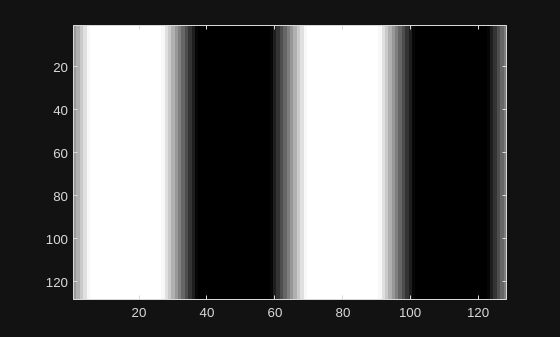


% Revisar nuevamente los valores mínimos y máximos
X = ceil(128*X);
image(X);
colormap(gray(128));

# Imagen a color

Las imagenes a color se construyen separando las capas de cada uno de los colores primarios RGB. A diferencia de lo que se ha explicado hasta ahora estas capas van de 0 a 1, de negro a intensidad máxima para cada una de las capas. Esta regla aplica de la misma forma para construir mapas de color que tengan cambios de color.

parula(16)

ans =     0.2422    0.1504    0.6603
    0.2717    0.2184    0.8439
    0.2814    0.3095    0.9483
    0.2647    0.4030    0.9935
    0.1847    0.5030    0.9819
    0.1540    0.5902    0.9218
    0.1085    0.6669    0.8734
    0.0009    0.7248    0.7815
    0.1609    0.7635    0.6671
    0.2809    0.7964    0.5266
    0.5044    0.7993    0.3480
    0.7344    0.7679    0.1852
    0.9184    0.7308    0.1890
    0.9962    0.7798    0.2095
    0.9619    0.8840    0.1557


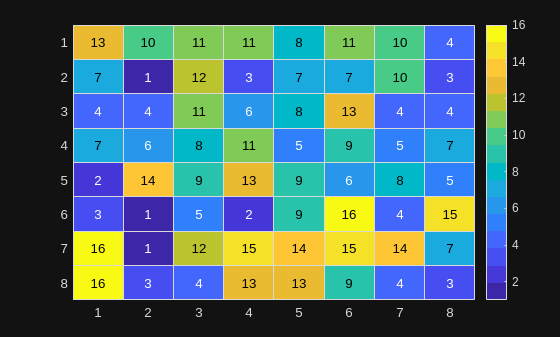

h = heatmap(randi([1, 16],[8, 8]));
h.Colormap = parula(16);

La paleta *parula *tiene una progesión del azul al amarillo, lo cual se puede observar analizando cada renglón. Ahora construiremos una matriz con colores aleatorios. Dado, que se especifica el valor de cada uno de los pixeles, el intérprete (Matlab) ya no hace caso del mapa de color y asigna el valor de acuerdo a los valores de la matriz 3D que se acaba de pasar.

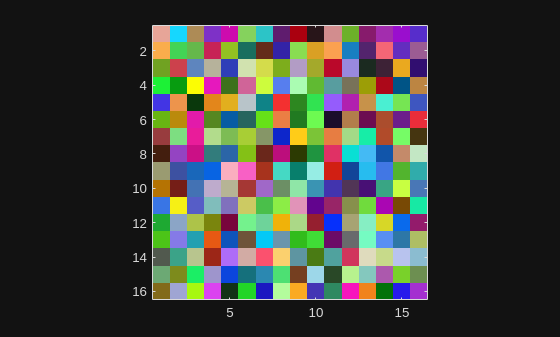

X = rand([16,16,3]);
image(X)
axis square

Otra función que permite visualizar las images son: ***imshow*** e ***imagesc***

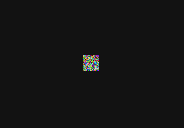

imshow(X)
axis tight

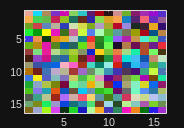

imagesc(X)

## Lectura de una imagen

Las imágenes, se cargan dentro de las variables de Matlab, como una matriz dimensional. En el caso de imágenes a color estas tienen dimensiones *largo x ancho x 3. *Donde la tercera dimensión hace referencia a las capas de color que se ocupan para generar la imagen.

X = imread("/home/erit/Desktop/SIMLab_2025/Imagenes/misc/4.1.07.tiff");
disp(['Dimensiones de la imagen:',string(size(X))]);

    "Dimensiones de la imagen:"    "256"    "256"    "3"



disp(['Minimo valor de la imagen: ', string(min(X(:)))])

    "Minimo valor de la imagen: "    "19"



disp(['Máximo valor de la imagen: ', string(max(X(:)))])

    "Máximo valor de la imagen: "    "218"



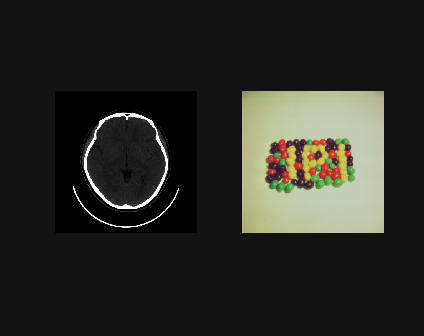

imshow(X);

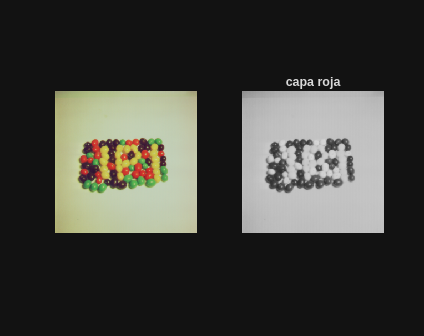

% capa roja

subplot(121)
imshow(X)
subplot(122)
imshow(X(:,:,1))
title('capa roja')

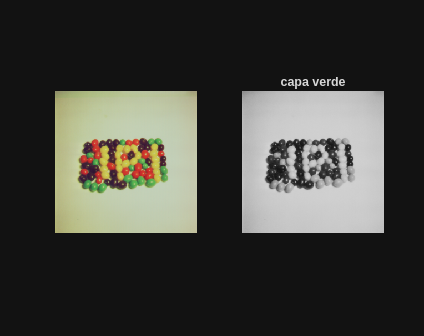

% capa verde
subplot(121)
imshow(X)
subplot(122)
imshow(X(:,:,2))
title('capa verde')

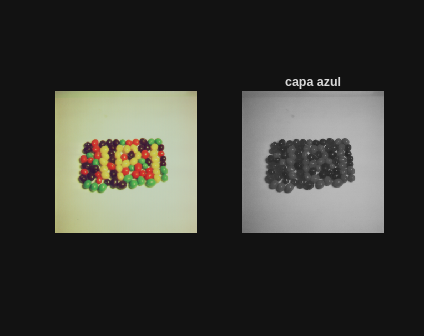

% capa azul
subplot(121)
imshow(X)
subplot(122)
imshow(X(:,:,3))
title('capa azul')

# Brillo y contraste de una imagen

## Brillo

El **brillo** de una imagen se refiere al **nivel medio de intensidad** de sus píxeles.

- En imágenes en escala de grises, corresponde a qué tan **clara u oscura** se percibe la imagen en su totalidad.

- Matemáticamente, suele asociarse con el **valor promedio** de los niveles de gris.

- En procesamiento médico, ajustar el brillo ayuda a resaltar estructuras cuando la imagen es demasiado oscura o demasiado clara por cuestiones de adquisición (ej. radiografías subexpuestas o sobreexpuestas).

## Contraste

El **contraste** mide la **diferencia relativa de intensidad** entre las regiones claras y oscuras de una imagen.

- Una imagen con **alto contraste** tiene zonas muy brillantes y muy oscuras bien diferenciadas.

- Una imagen con **bajo contraste** se ve “plana” o “lavada”, con poca diferencia entre intensidades.

- Matemáticamente, puede relacionarse con la **dispersión de los niveles de gris** (ej. la varianza o el rango dinámico).

- En imágenes médicas, mejorar el contraste facilita distinguir estructuras y tejidos que tienen intensidades similares (ej. distinguir órganos en una tomografía).

X = imread("/home/erit/Desktop/SIMLab_2025/Imagenes/stack_mri_sagital/mri_sagital.44");
disp(['Valor medio de la imagen= ' num2str(mean(X(:)))])

Valor medio de la imagen= 22.3567


disp(['Varianza de la imagen = ' num2str(std(double(X(:))))])

Varianza de la imagen = 29.7642


disp(["tipo de datos de X: ", class(X)])

    "tipo de datos de X: "    "uint8"



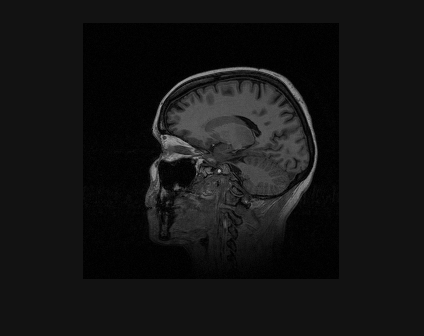

subplot(111)
imshow(X)

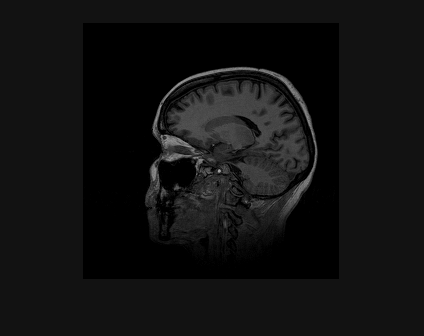

imshow(X+-10)

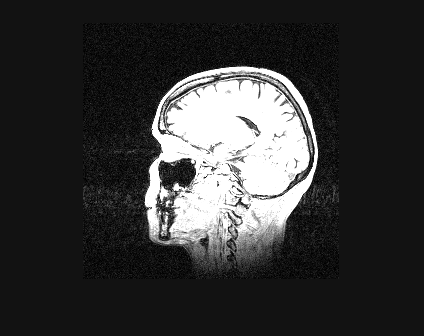

imshow(6.01*X + 0)

# Normalización de imagen

Para facilitar la visualización de imagen los valores de una imagen se escalan para ubicarlos dentro del rango [0,1]. Esto se logra mediante la siguiente ecuación:


$$X_{norm} = \frac{X - X_{min}}{X_{max}- X_{min}}$$


Donde $X_{min}$ corresponde al mínimo valor de la matriz y $X_{max}$ a suvalor máximo. Este proceso se llama *normalización* de la imagen. Una vez que la imagen está normalizada esta puede ser visualizada multiplicando por el valor de niveles de gris y redondeando al valor más alto.


$$X_{img} = \left \lceil{X_{norm} \cdot N_{gris}} \right \rceil$$


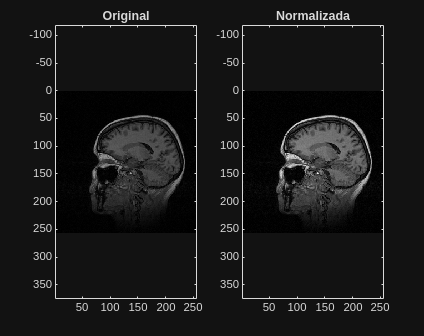

X = double(X);
Xnorm = (X - min(X(:)))/(max(X(:))-min(X(:)));

colormap(gray(256))
subplot(121)
image(X)
axis equal
title('Original')
subplot(122)
image(Xnorm * 256)
axis equal
title('Normalizada')

# Trabajo en clase

- Construya una imagen que vaya en gradiente de blanco a negro en forma de diente de sierra. El tamaño de la imagen es de 512 x 512 y los dientes tienen una periodicidad de 128. Use un mapa de color de 256 niveles.

- Cargue una imagen de color e invierta los valores de cada una de las capas de color, i.e. $X_{inv} = 1-X$

- Cargue una imagen en blanco y negro. Indique cual es el valor mínimo y máximo de la imagen, y mediante la normalización muestre la imagen usando un mapa de color de 256 niveles.